%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path



clearvars %clear all variables
%clear all % clear all, men forsinker koden om den kjøres hver gang
% clf %clear all figures
% cla %clear all axis






# Komplekse tall

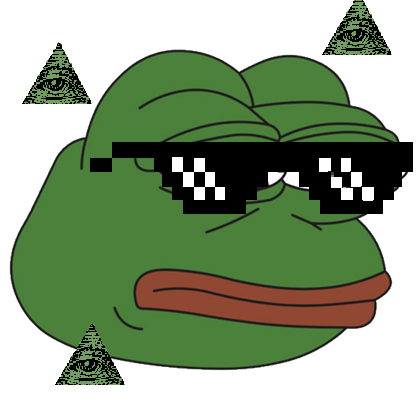

**Velg type evaluering**

typeEvaluering = 1;
 

**Evaluer et komplekst uttrykk**

Eksempel: 1/i-(1-i)/(1+i)

if typeEvaluering == 1
    z = i+eulersFormula(3,-90)+(2-i)/i
    theta = sym(angle(z)); % Finner vinkel theta
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    
    zConj = conj(z)
    zDivByZConj = z/zConj
    zTimesZConj = z*zConj
    expFormExponent = (1i*theta); % Finner den eksponentielle delen av eksponentiell form. S338 i Engineering Mathematic.
    if theta ~= 0
        displayFormula(["'Eksponentiell form = e^('", string(expFormExponent),"')'"])       
    end
    disp(func2link(z))
end

$$z = -1-4\,\mathrm{i}$$

$$zConj = -1+4\,\mathrm{i}$$

$$zDivByZConj = -\frac{15}{17}+\frac{8}{17}\,\mathrm{i}$$

$$zTimesZConj = 17$$

$$\mathrm{Eksponentiell form = e\hat{}(}\mathrm{atan}\left(4\right)\,\mathrm{i}-\pi \,\mathrm{i})$$

<a href="https://www.wolframalpha.com/input/?i=-1-4i">Vis funksjon i wolfram</a>


**Evaluer en kompleks likning**

Eksempel: @(z) z^3==1

if typeEvaluering == 2

    
    
    syms z
    zEqn = "@(z) z^4==-1";
    zEqn = str2func(zEqn);
    disp(zEqn);
    z = solve(zEqn,z)

    theta = sym(angle(z)); % Finner vinkel theta i radianer
    thetaDegrees = rad2deg(theta); % Vinkel theta i grader
    r = sym(abs(z)); % Modulus, absoluttverdi, r
    
    zConj = conj(z)
    zDivByZConj = z./zConj
    zDivByZConjDouble = double(z./zConj)
    zTimesZConj = z.*zConj
    zTimesZConjDouble = double(z.*zConj)
    sumOfZs = sum(z)
end

**Cartesian Argand**

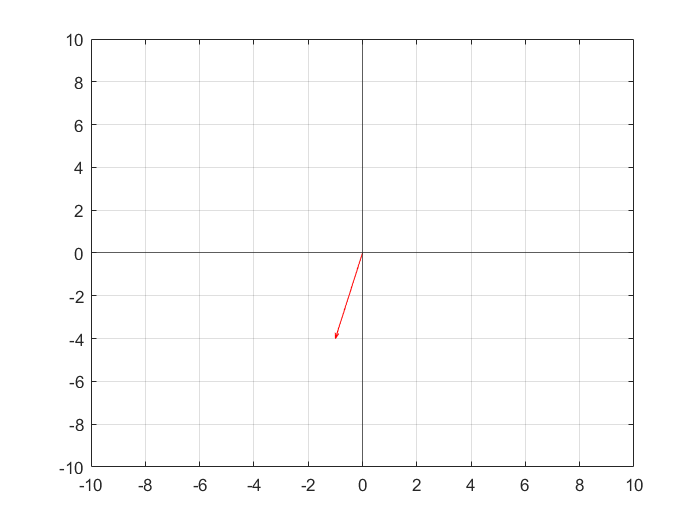

realPart = real(z);
imagPart = imag(z);
clf
cla

syms x y(x)

quiver(0,0,realPart,imagPart,0, 'color', 'red')
hold on
axis([-10 10 -10 10]) % sett denne manuelt om zoomen blir feil
yline(0)
xline(0)
grid on
hold off

**Polar Argand**

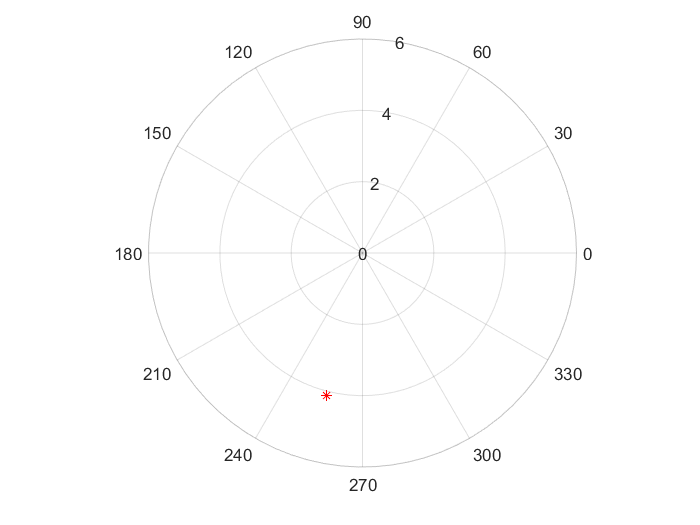

polarplot(z,'*',"Color",'red')
rlim('auto') % hent denne verdien fra funksjonen

display(theta);

$$theta = \mathrm{atan}\left(4\right)-\pi$$

display(thetaDegrees);

$$thetaDegrees = -\frac{180\,\pi -180\,\mathrm{atan}\left(4\right)}{\pi }$$

display(r);

$$r = \sqrt{17}$$

% displayFormula(["'Vinkel theta  =  '", string(theta), "' radianer  =  '", string(thetaDegrees), "' grader.'"]);
% displayFormula(["'Modulus r = '", string(r)])